# Assignment 3 - Explicit and implicit integrators

## 2) 

a)

clear; 
clc;

dt = 0.1; lambda = -2; tf = 2; x0 = 1;
f = @(u, x) lambda*x;

A1 = 0; b1 = 1; c1 = 0;
A2 = [0 0; 1/2 0]; b2 = [0 1]; c2 = [0; 1/2];
A4 = [0 0 0 0; 1/2 0 0 0; 0 1/2 0 0; 0 0 1 0]; b4 = [1/6 1/3 1/3 1/6]; c4 = [0; 1/2; 1/2; 1];

[t1, x1] = erk_sol(x0, f, tf, dt, A1, b1, c1);
[t2, x2] = erk_sol(x0, f, tf, dt, A2, b2, c2);
[t4, x4] = erk_sol(x0, f, tf, dt, A4, b4, c4);

x1_end = x1(end)

x1_end = 0.0115

x2_end = x2(end)

x2_end = 0.0189

x4_end = x4(end)

x4_end = 0.0183

xex = exp(lambda*tf)

xex = 0.0183


Err1 = abs(x1_end-xex)/abs(xex)

Err1 = 0.3705

Err2 = abs(x2_end-xex)/abs(xex)

Err2 = 0.0315

Err4 = abs(x4_end-xex)/abs(xex)

Err4 = 6.3033e-05

b)

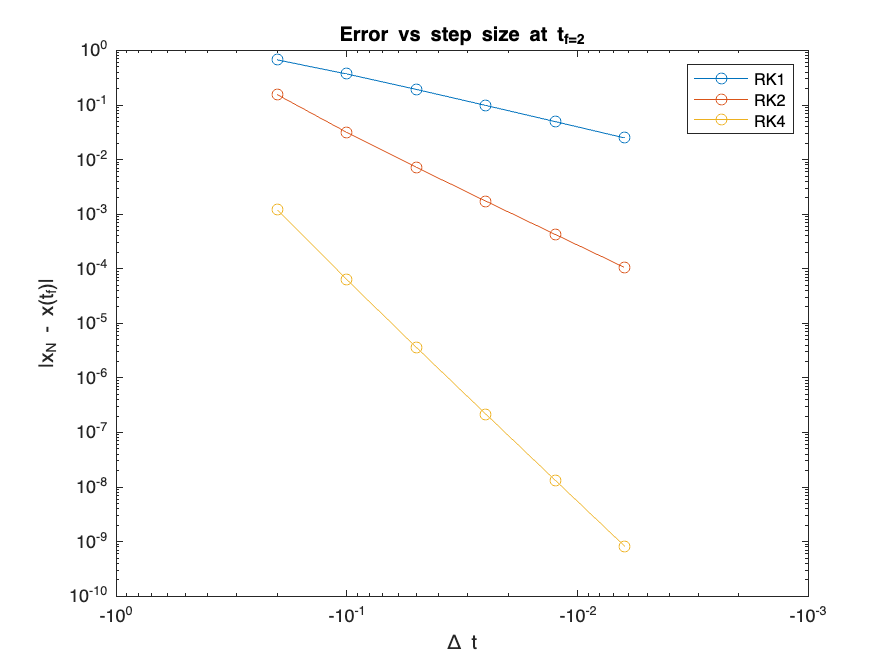

dts = 0.2 ./ (2.^(0:5));
err1 = zeros(size(dts)); err2 = err1; err4 = err1;
for k = 1:numel(dts)
    dt = dts(k);
    [t1, x1] = erk_sol(x0, f, tf, dt, A1, b1, c1);
    [t2, x2] = erk_sol(x0, f, tf, dt, A2, b2, c2);
    [t4, x4] = erk_sol(x0, f, tf, dt, A4, b4, c4);
    x1_end = x1(end);
    x2_end = x2(end);
    x4_end = x4(end);
    err1(k) = abs(x1_end-xex)/abs(xex);
    err2(k) = abs(x2_end-xex)/abs(xex);
    err4(k) = abs(x4_end-xex)/abs(xex);
end

figure;
loglog(-dts, err1, 'o-', 'DisplayName', 'RK1'); hold on
loglog(-dts, err2, 'o-', 'DisplayName', 'RK2')
loglog(-dts, err4, 'o-', 'DisplayName', 'RK4')
xlabel('\Delta t'); ylabel('|x_N - x(t_{f})|'); legend; title('Error vs step size at t_f=2');
box on

c)

mu = linspace(-5, 0, 5001);
dt = 0.1;

R1 = erk_R(mu, 1);
mu1_min = mu(find(abs(R1)<=1, 1, "first"));
R2 = erk_R(mu, 2);
mu2_min = mu(find(abs(R2)<=1, 1, "first"));
R4 = erk_R(mu, 4);
mu4_min = mu(find(abs(R4)<=1, 1, "first"));

lambda1_min = mu1_min / dt

lambda1_min = -20

lambda2_min = mu2_min / dt

lambda2_min = -20

lambda3_min = mu4_min / dt

lambda3_min = -27.8500

## 3.

a)

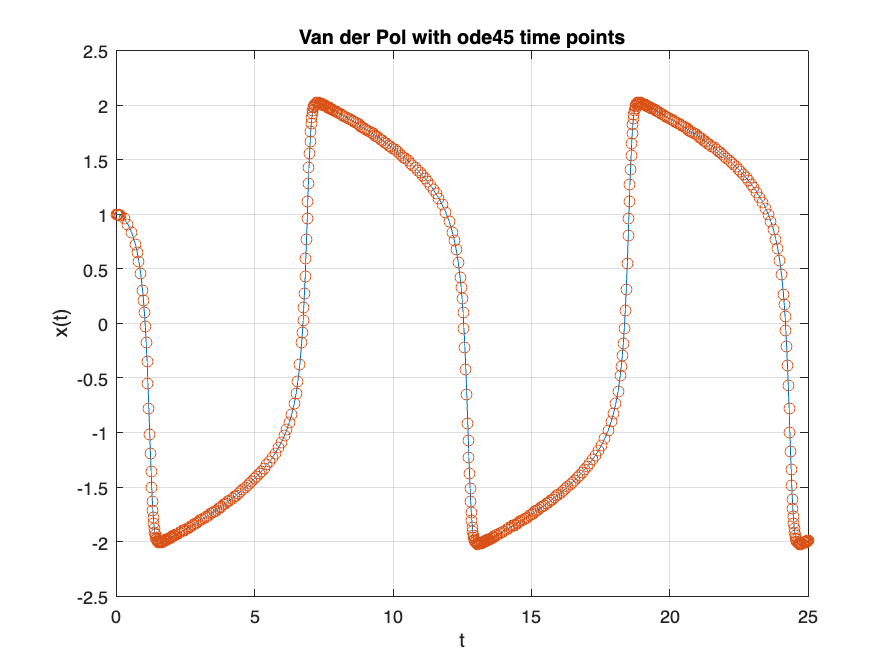

options = odeset();

u = 5;
tf = 25;
tspan = [0 25];
y0 = [1; 0];

vdp = @(t,y) [y(2); u*(1-y(1)^2)*y(2)-y(1)];

[t, y] = ode45(vdp, tspan, y0, options);

% Plot x(t) with solver time points
figure; plot(t, y(:,1), '-'); hold on
plot(t, y(:,1), 'o', 'MarkerSize', 6)
xlabel('t'); ylabel('x(t)'); title('Van der Pol with ode45 time points'); grid on

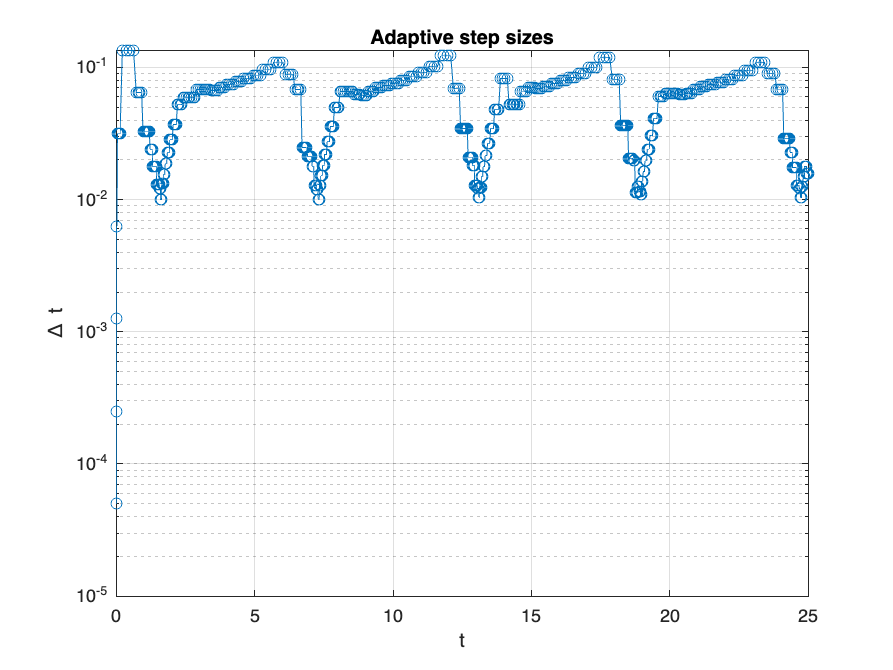


% Step-size history
dt = diff(t); tm = (t(1:end-1)+t(2:end))/2;
figure; semilogy(tm, dt, '-o'); grid on
xlabel('t'); ylabel('\Delta t'); title('Adaptive step sizes')

b)

tol = 1e-8;
options = odeset('AbsTol',1e-8,'RelTol',1e-8);
sol = ode45(vdp, tspan, y0, options);

% Halving loop for fixed-step RK4
dt = 0.1; max_halvings = 8;
errs = []; dts = [];

for k = 1:max_halvings
    [t_rk, Y_rk] = erk_sol(y0, vdp, tf, dt, A4, b4, c4);

    % Evaluate ode45 solution at RK4 grid using deval
    Y_ode_on_rk = deval(sol, t_rk);

    % Global error (max over time, both components)
    err = max( max(abs(Y_rk(1,:) - Y_ode_on_rk(1,:)), [], 1) );

    errs(end+1) = err; dts(end+1) = dt;
    fprintf('dt=%g   max-norm error = %.3e\n', dt, err);

    if err <= tol
        break
    end
    dt = dt/3;
end

dt=0.1   max-norm error = 3.334e-01
dt=0.0333333   max-norm error = 5.030e-03
dt=0.0111111   max-norm error = 7.215e-05
dt=0.0037037   max-norm error = 1.288e-06
dt=0.00123457   max-norm error = 3.795e-07
dt=0.000411523   max-norm error = 3.682e-07
dt=0.000137174   max-norm error = 3.681e-07
dt=4.57247e-05   max-norm error = 3.681e-07


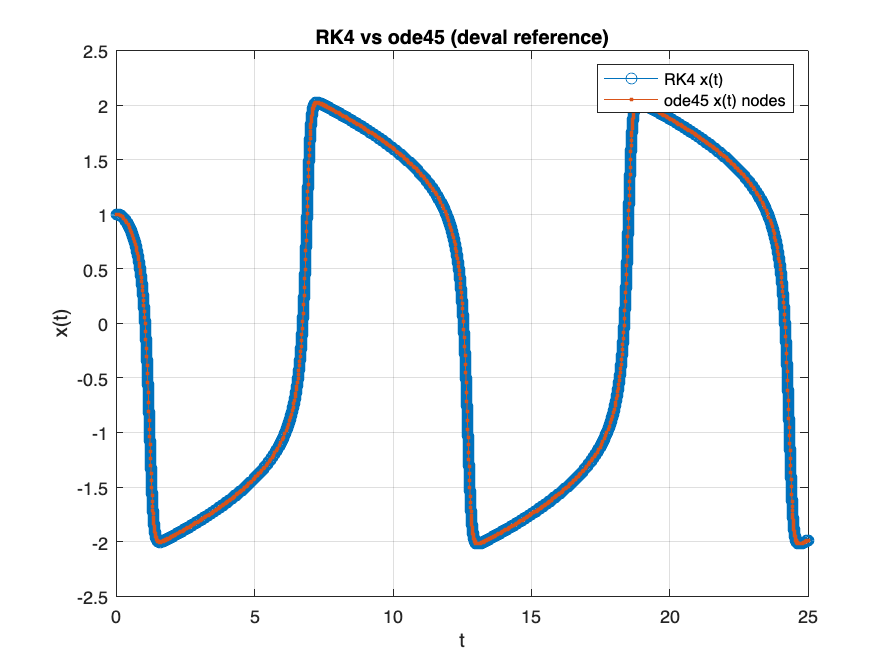


figure;
plot(t_rk, Y_rk(1,:), 'o-', 'DisplayName','RK4 x(t)'); hold on
plot(sol.x, sol.y(1,:).', '.-', 'DisplayName','ode45 x(t) nodes');
grid on; xlabel('t'); ylabel('x(t)'); legend; title('RK4 vs ode45 (deval reference)')

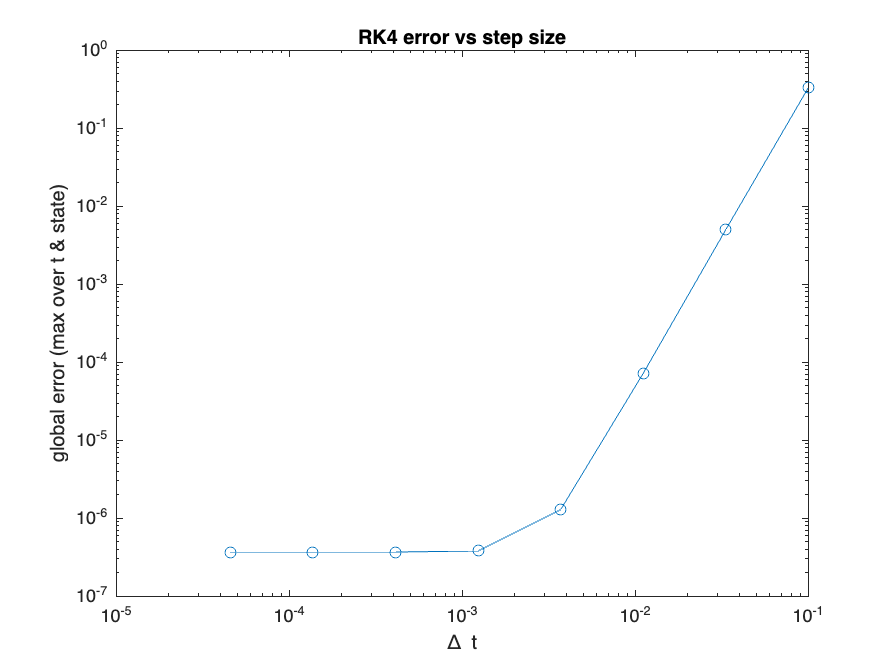


figure;
loglog(dts, errs, 'o-');
xlabel('\Delta t'); ylabel('global error (max over t & state)'); title('RK4 error vs step size')

## 4.

a) See function irk_sol

## Defining the Butcher array for RK4


s = 2;
A = [1/4 1/4-(sqrt(3)/6);1/4+(sqrt(3)/6) 1/4];
c = [1/2-(sqrt(3)/6) 1/2+(sqrt(3)/6)];
b = [1/2 1/2];


## b)

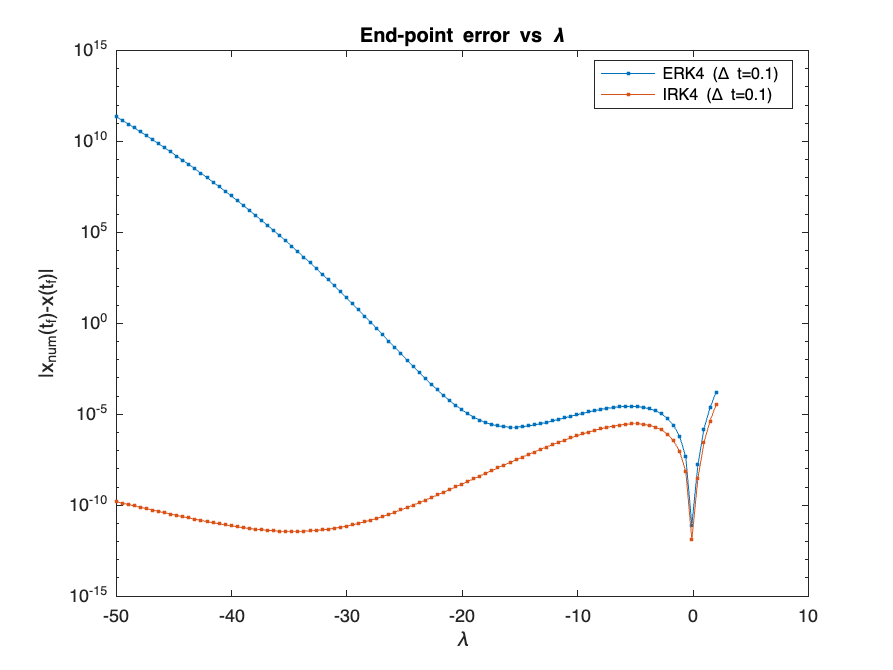

n = 1;
syms t lambda real
x = sym('x',[n,1]);
f_b = lambda * x;
matlabFunction(f_b, 'file', 'Stability','vars',{t,x,lambda});
clear x lambda t

% Defining r(xNext,x,u):
x = sym('x',[n,1]);
syms t dt lambda real

% Create K as column vector from the start
K = sym('K', [n*s, 1]);
% Reshape for computation
K_mat = reshape(K, [n, s]);
r_mat = sym('r', [n, s]);

for i = 1:s
    r_mat(:, i) = Stability(t + c(i)*dt, x + dt * K_mat * A(i,:).', lambda) - K_mat(:,i);
end

% Reshape r to vector
r = reshape(r_mat, [n*s, 1]);
% K is already in the right form - don't reshape it again!
dr = jacobian(r, K);
matlabFunction(r, dr, 'file', 'rIRK4_b', 'vars', {t, x, K, dt, lambda});
clear K x t dt lambda r dr r_mat K_mat

%% Simulation params
tf = 1;
dt = 0.1;
x0 = 1;
lambda_vec = linspace(-50, 2, 100);
err_erk4 = nan(size(lambda_vec));
err_irk4 = nan(size(lambda_vec));
for k = 1:numel(lambda_vec)
    lam = lambda_vec(k);
    % ERK4: pass f(t,x) with λ captured
    f = @(tt,xx) Stability(tt, xx, lam);
    [tE, xE] = erk_sol(x0, f, tf, dt, A4, b4, c4);
    xE_end = xE(1,end);
    % IRK4: pass residual with λ captured
    Rfun = @(tt,xx,K,hh) rIRK4_b(tt, xx, K, hh, lam);
    [tI, xI] = irk_sol(Rfun, x0, tf, dt, b, n, s);
    xI_end = xI(1,end);
    xex = x0 * exp(lam * tf);
    err_erk4(k) = abs(xE_end - xex);
    err_irk4(k) = abs(xI_end - xex);
end
figure;
semilogy(lambda_vec, err_erk4, '.-', 'DisplayName','ERK4 (\Delta t=0.1)'); hold on
semilogy(lambda_vec, err_irk4, '.-', 'DisplayName','IRK4 (\Delta t=0.1)');
xlabel('\lambda'); ylabel('|x_{num}(t_{f})-x(t_{f})|');
title('End-point error vs \lambda'); legend('Location','best');

## c)

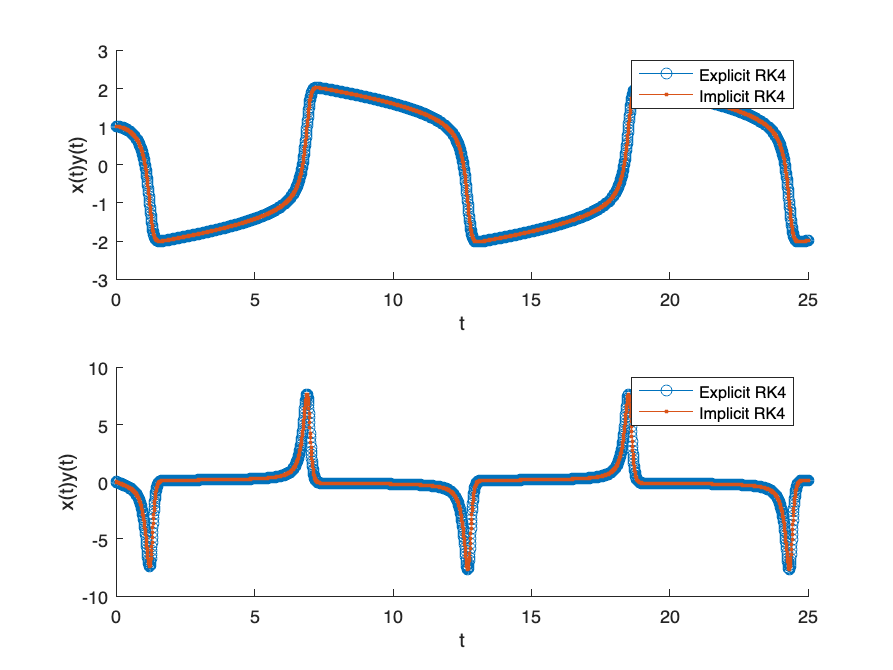

n = 2;
s = 2;
x = sym('x',[n,1]);
syms t real
f_c = [ x(2);
5*(1-x(1)^2)*x(2) - x(1)];
matlabFunction(f_c, 'file', 'VanDerPol','vars',{t,x});
clear x t f
% Defining r(xNext,x,u):
x = sym('x',[n,1]);
% Define K and r as nxs-matrices
K_mat = sym('K', [n, s]);
r_mat = sym('r', [n, s]);
syms t dt real
for i=1:s
    r_mat(:, i) = VanDerPol(t + c(i)*dt, x + dt * K_mat * A(i,:)') - K_mat(:,i);
end
% Reshape K and r to vectors to enable computation of jacobian
r = reshape(r_mat, [n*s, 1]);
K = reshape(K_mat, [n*s, 1]);
dr = jacobian(r,K);
matlabFunction(r,dr, 'file', 'rIRK4_c','vars',{t,x,K,dt});
clear K x t dt r dr

% Simulation parameters:
tf = 25;
dt = 1e-2;
x0 = [1;0];

% solve using both ERK4 and IRK4
[t.erk4, x.erk4] = erk_sol(x0, @VanDerPol, tf, dt, A4, b4, c4);
[t.irk4, x.irk4] = irk_sol(@rIRK4_c, x0, tf, dt, b, n, s);

diff = abs(x.irk4 - x.erk4);

names = ['x(t)', 'y(t)'];
d = dictionary(1:n, names);

figure;
for subfig = 1:n
    subplot(n,1,subfig);hold on
    plot(t.erk4,x.erk4(subfig,:),'o-')
    plot(t.irk4,x.irk4(subfig,:),'.-')
    legend('Explicit RK4','Implicit RK4'); xlabel('t'); ylabel(d(subfig));
end

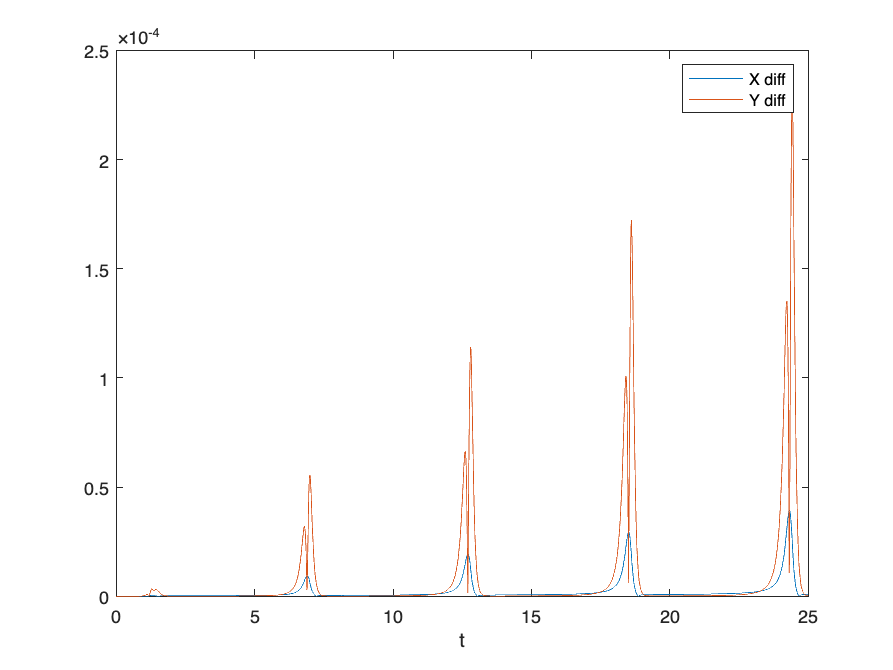

figure;
plot(t.irk4, diff); legend('X diff', 'Y diff');
xlabel('t');

function val = erk_R(mu, s)
% R(mu) = sum_{k=0}^s mu^k / k!
    val = 0;
    for k = s:-1:0
        val = val.*mu + 1/factorial(k);
    end
end

function [t, x] = erk_sol(x0, f, tf, dt, A, b, c)
    n = numel(x0); s = numel(b);
    N = round(tf/dt);

    b = b(:); c = c(:);

    % preallocate output
    t = 0:dt:tf;        
    x = zeros(n, N+1);
    x(:,1) = x0(:);

    for k = 1:N
        K = zeros(n, s);     
        for i = 1:s
            if i == 1
                xi = x(:,k);
            else
                % xi = x + dt * sum_{j<i} a_{ij} K_j
                xi = x(:,k) + dt * ( K(:,1:i-1) * A(i,1:i-1).' );
            end
            ti = t(k) + c(i)*dt;
            K(:, i) = f(ti, xi);  
        end
        x(:,k+1) = x(:, k) + dt * K * b;     
    end
end

function [t, x] = irk_sol(rIRK, x0, tf, dt, b, n, s)

    Nsteps = round(tf/dt);
    t = 0:dt:tf;
    x = zeros(n, Nsteps+1);
    x(:,1) = x0(:);

    b = b(:);

    for k = 1:Nsteps
        % stages vector initial guess: [xk; xk; ...] (n*s × 1)
        K = repmat(x(:,k), s, 1);

        % Newton
        while true
            [r, dr] = rIRK(t(k), x(:,k), K, dt);
            if norm(r, inf) < 1e-10
                break; 
            end
            K = K - dr \ r;
        end

        % update
        K_mat = reshape(K, [n, s]);
        x(:,k+1) = x(:,k) + dt * (K_mat * b);
    end
end

